% 使用自定义核训练 SVM 分类器

## 导入数据

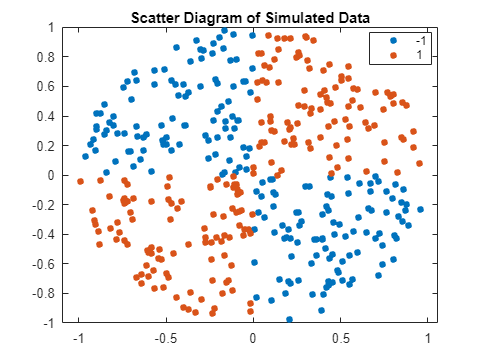

clear
SVM_Data1

## 使用调整后的 sigmoid 核训练另一个 SVM 分类器。

Mdl2 = fitcsvm(X,Y,'KernelFunction','mysigmoid2','Standardize',true);
[~,scores2] = predict(Mdl2,xGrid);

Unrecognized function or variable 'xGrid'.

## 绘制数据和决策区域，

figure;
h(1:2) = gscatter(X(:,1),X(:,2),Y);
hold on
h(3) = plot(X(Mdl2.IsSupportVector,1),...
    X(Mdl2.IsSupportVector,2),'ko','MarkerSize',10);
title('Scatter Diagram with the Decision Boundary')
contour(x1Grid,x2Grid,reshape(scores2(:,2),size(x1Grid)),[0 0],'k');
legend({'-1','1','Support Vectors'},'Location','Best');
hold off

## 并确定样本外的误分类率。

CVMdl2 = crossval(Mdl2);
misclass2 = kfoldLoss(CVMdl2);
% misclass2 =    0.0450

% 在 sigmoid 斜率调整后，新决策边界似乎提供更好的样本内拟合，
% 交叉验证率收缩 66% 以上。